## Introduction

In this module, we will delve into the intricacies of the Sampling Theorem, a fundamental concept in signal processing and digital communications. Our exploration will consist of three key steps: 

-  We will start by considering an example continuous-time signal to serve as our test case, 

- proceed to sample this signal at discrete intervals, and 

- finally, utilize the ideal interpolation technique specified by the Sampling Theorem to reconstruct the original continuous-time signal. 

Through this process, we aim to illustrate the practical implications of the theorem and offer insights into the conditions under which perfect signal reconstruction is possible.

Consider a signal $x(t)$sampled at a frequency $F_s$ to obtain samples $x[n]$. The sampling theorem states that if the bandwidth $B$ of the signal $x(t)$ is less than $F_s/2$, then the signal $x(t)$ can be recovered exactly from just the samples $x[n]$ using 

$x(t) = \frac{2B}{F_s}\sum_{n=-\infty}^{\infty}{x[n]g\left( t-\frac{n}{F_s}\right)$, 

wher the function $g(t)$ is given as 


$$g(t) = \frac{sin(2\pi B t)}{2\pi Bt)$$


Note that in most textbooks, it is customary to assume $F_s = 2B$ and therefore you won't see you scaling factor in front of the summation.

## Sampling a continuous time signal

First, let us pick a continuous signal to sample. We will sample the following signal: 


$$x(t) = sin(\pi t) sin(2\pi F t)$$


for $F=10$, and $0 \le t \le 1$. 

### Plotting the continuous time signal

How will this signal look like? Note that in order to plot this signal on a computer, we have to sample it! For the purpose of visualization, we will pick a very high sampling rate and plot the signal by linearly interpolating between the sample values. We will call this high sampling rate $F_c$ and we will set it as $F_c = 100*F$. 

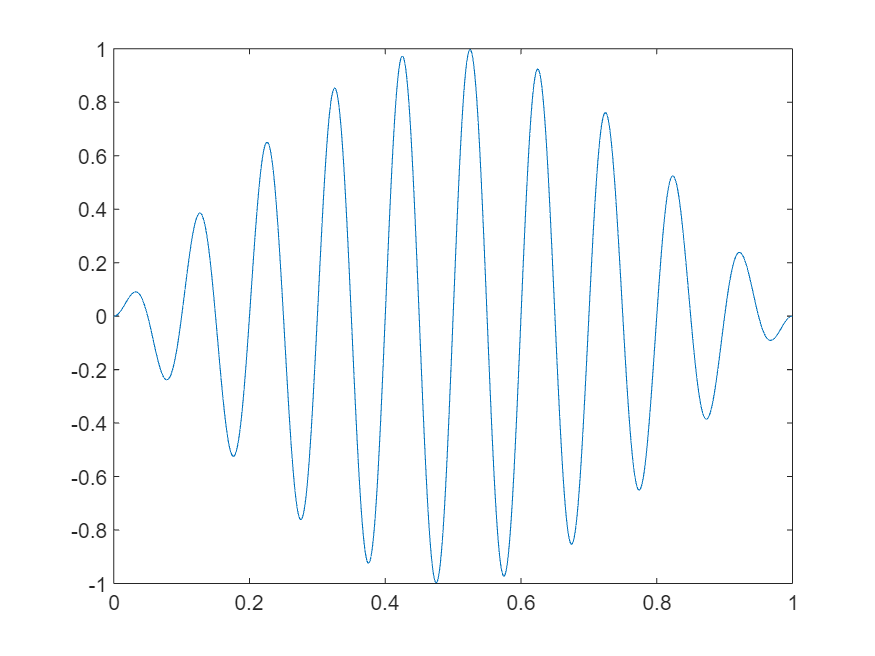

F = 10; 
Fc = 100*F; 
Ts = 0:1/Fc:1; %sample times 
xc = sin(pi*Ts).*sin(2*pi*F*Ts); %xc is an array which holds the samples of x(t)
plot(Ts,xc); %the plot function linearly interplotes between values

Note that in the above figure, the actual samples are very closely spaced (there are 1001 sample points) to create a plot which looks like a "continuous" signal. 

### Bandwidth of the signal

Since the sampling theorem relates the sampling rate to the bandwidth of the signal, a natural question to ask here is: What is the bandwidth of the signal $x(t)$? We can plot the spectrum of the signal to investigate this. A spectrum shows how the energy of the signal is distributed amongst various frequencies. (There is an exact mathematical definition for this, but for now, lets go with it). 

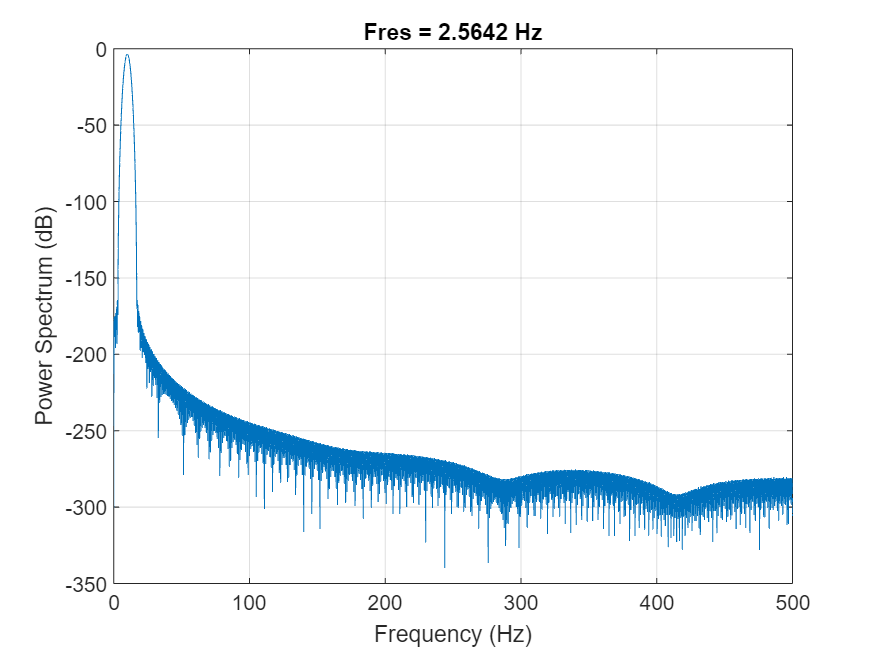

pspectrum(xc,Fc)

As seen in the above plot, most of the signal's energy is concentrated in the lower frequencies. Note that the y-axis is in log-scale (decibels). Notice also that the signal's energy in higher frequencies is never zero! So, this is not technically a finite bandwidth signal, and the sampling theorem does not exactly apply to this example signal. However, we will come close and any errors we will see in the reconstruction can be attributed to this discrepancy between the theorem's statement and our example signal. 

Now let's zoom into the lower frequencies and see how the plot looks like. 

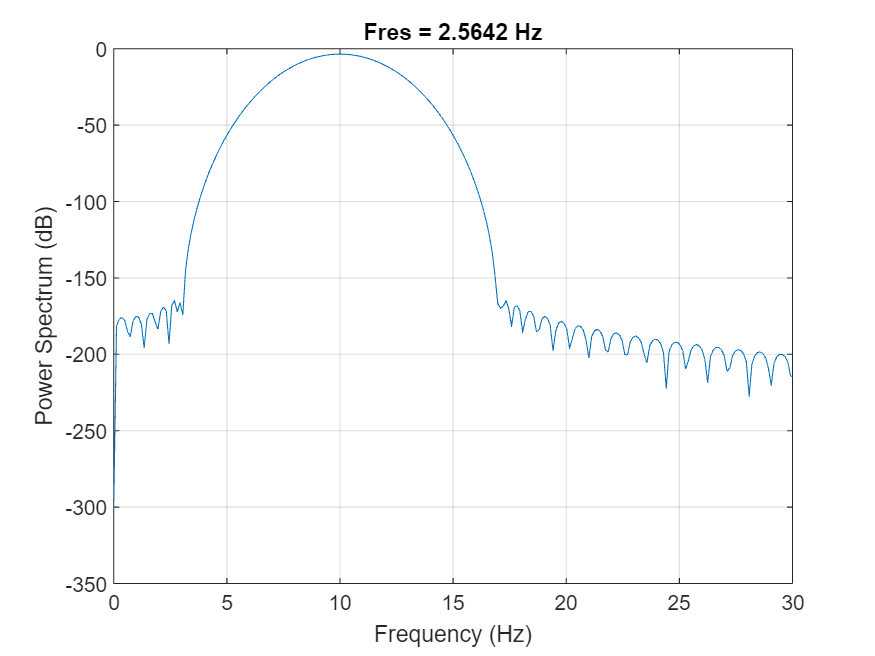

hold on; 
xlim([0,30])
hold off; 

From the above plot, we can reasonably say that most of the signal's energy is concentrated below 18 Hz, which we will consider as the signal's bandwidth $B = 18$. 

### Sampling the signal

For the sampling theorem to apply, we need the sampling rate to be greater than $2B = 36$Hz. We will set $F_s = 38$Hz as the sampling rate. Note that is very close to the cut-off specified by the sampling theorem and much less than 1000Hz which was used to create the plot above. We can now obtain the samples. 

B = 18; 
Fs = 2.2*B; 
Ts1 = 0:1/Fs:1; %sampling times 
xn = sin(pi*Ts1).*sin(2*pi*F*Ts1); %xn is array which contains the samples 

Now, lets visaulize these samples by superimposing them on the original signal 

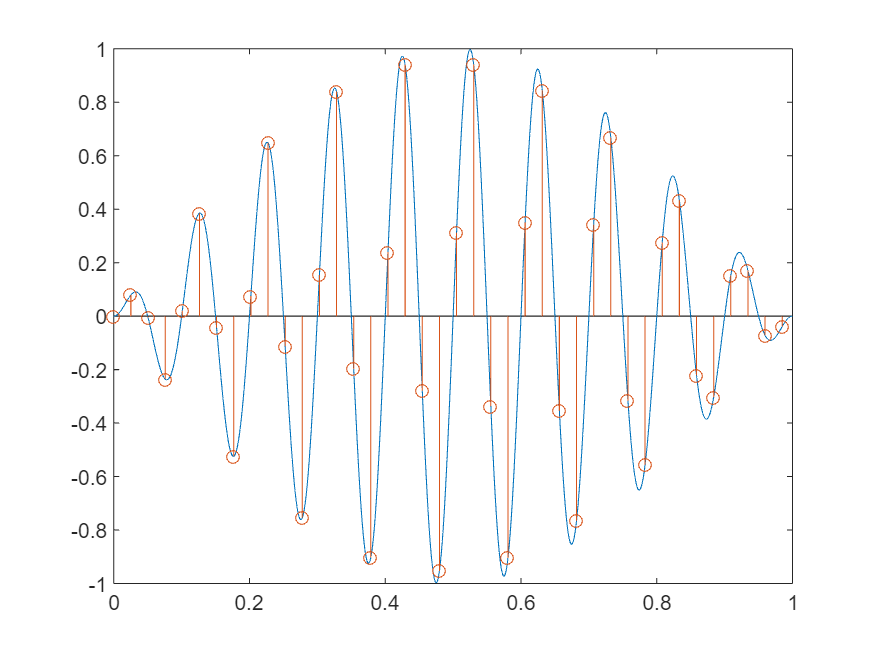

plot(Ts, xc); 
hold on; 
stem(Ts1, xn); 
hold off; 

The blue curve shows the original continuous signal and the sample values are superimposed using the stem plot. 

It is important to emphasize how sparse these samples are. To see this, let's plot just the sample points using the very high sampling rate $F_c$ we used to visualize a continuous signal vs the  samples with sampling rate $F_s$. 

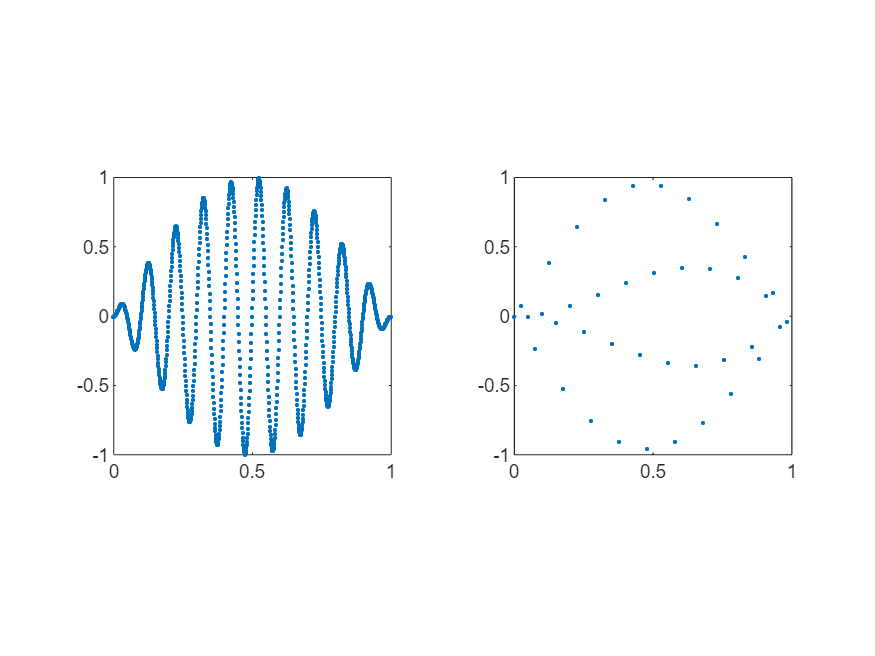

tiledlayout(1,2); 
nexttile
plot(Ts,xc, '.'); 
axis square
nexttile
plot(Ts1, xn, '.'); 
axis square

In the first plot, the samples are so densely packed that it is easy to see what the underlying continuous signal is. We cannot say the same for the second plot, but the sampling theorem tells us that these samples are sufficient to get back the original signal! Let's see this in action. 

## Reconstructing the signal

As stated in the beginning, we will use the following formula to get back the signal

$x(t) = \sum_{n=-\infty}^{\infty}{x[n]g\left( t-\frac{n}{F_s}\right)$, $g(t) = \frac{sin(2\pi B t)}{2\pi Bt)$

First we will compute the functions $x[n]g\left(t-\frac{n}{F_s}\right)$

shiftedWeightedSincs = zeros(length(Ts1),length(Ts)); 
for ii = 0:length(Ts1)-1
    shiftedWeightedSincs(ii+1,:) = xn(ii+1)*sinc(2*B*(Ts-ii/Fs)); 
end


Let's plot on of these functions and see how it looks like

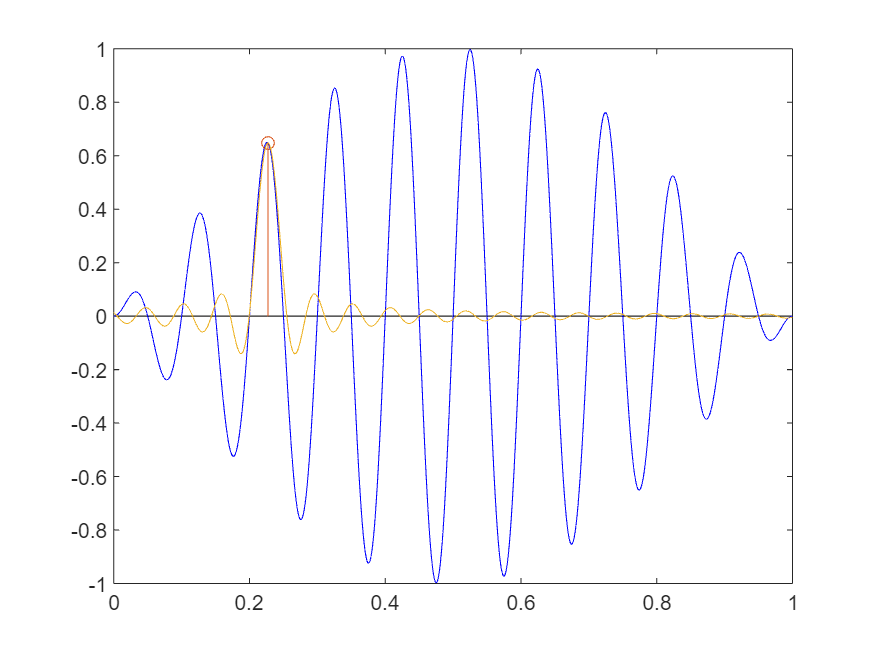

figure()
plot(Ts,xc, 'b'); 
hold on; 
a = 10; 
stem(Ts1(a),xn(a)); 
plot(Ts, shiftedWeightedSincs(a,:)); 

The above plot shows one of the weighted and shifted function superimposed on the original curve. This function is called a "sinc" function. 

Lets plot a few more 

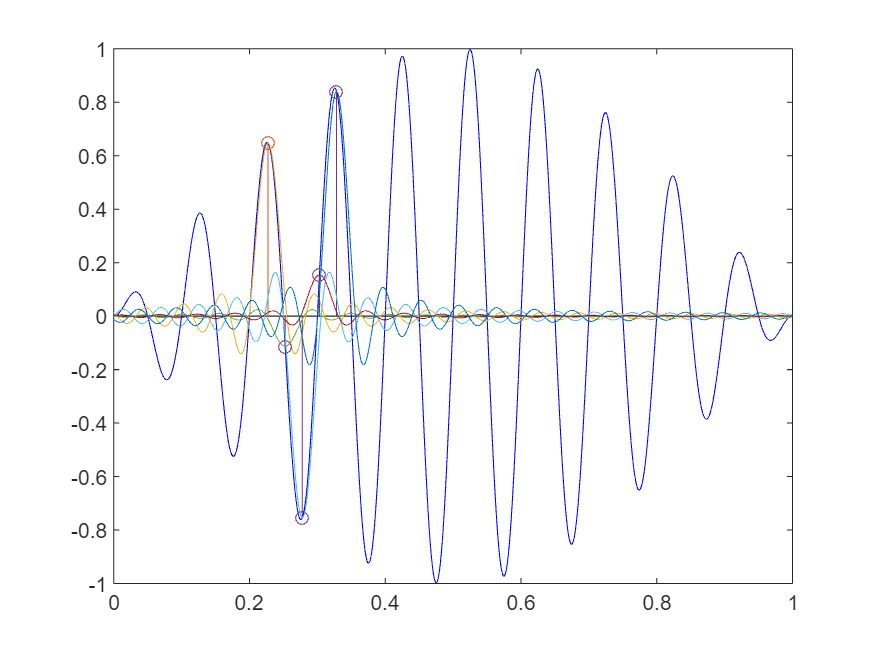

hold on; 
a = 11:14; 
stem(Ts1(a),xn(a)); 
plot(Ts, shiftedWeightedSincs(a,:)); 
hold off; 

The sampling theorem says that if we add up all these functions, we should get back the original signal. Again, completely non-obvious!! 

We will now add all these functions, and compare the result with the original curve

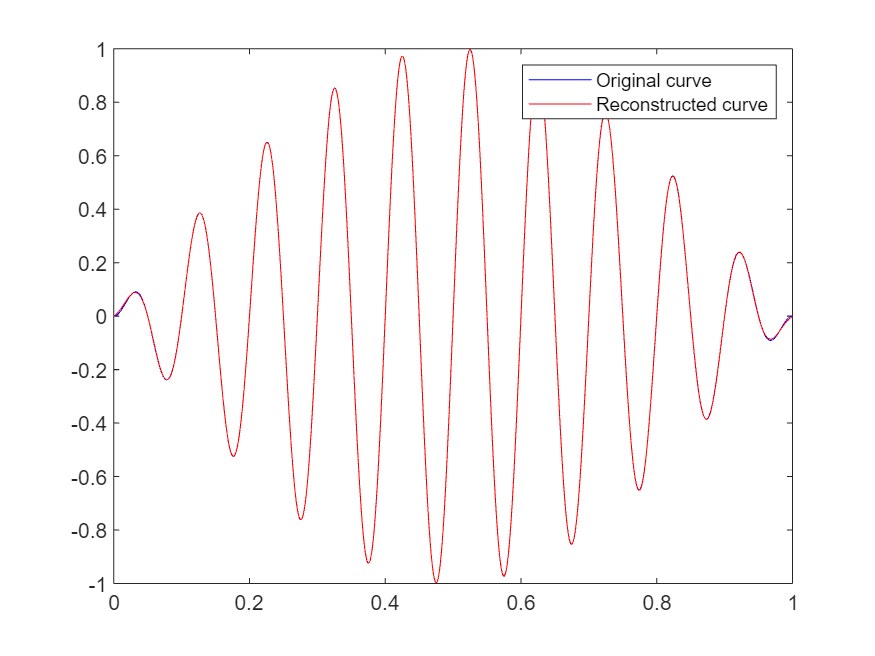

xr = (2*B/Fs)*sum(shiftedWeightedSincs,1); 
figure()
plot(Ts,xc,'b', 'DisplayName','Original curve'); 
hold on; 
plot(Ts,xr, 'r', 'DisplayName','Reconstructed curve'); 
hold off; 
legend()